# Práctica 1

## Ejercicio 1

#### 1.1

arbol = "arbol_640x426.jpg";
disp('Ej. 1.1')

Ej. 1.1


imread(arbol)

ans = 426×640×3 uint8 array
ans(:,:,1) =

    15    14    15    16    15    13    17    23    14    14    14    14    15    15    14    13    13    17    19    16    15    17    16    14    16    15    14    16    16    14    15    16    16    16    12    16    13    18    14    15    14    13    19    17    20    14    15    13    18    12    12    19    12    13    21    13    15    15    15    16    16    15    16    17    62    10     7    25    20     8    10    18    17    16    14    17    15    14    20    15    18    16    16    14    18    14    21    16    20    17    18    19    20    17    18    20    18    25    13    17    21    20    15    21    18    21    13    23    21    17    15    18    17    15    17    25    16    23    14    19    40    18    32    12    22    18    16    20    19    19    18    17    19    20    19    17    21    14    17    18    22    17    19    19    18    19    21    20    19    18    18    19    18    18    18    18    18    18    18    

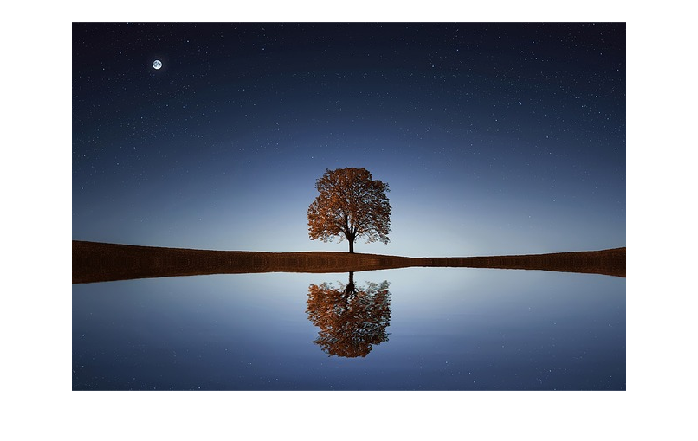

imshow("arbol_640x426.jpg")

#### 1.2

disp('Ej. 1.2');

Ej. 1.2


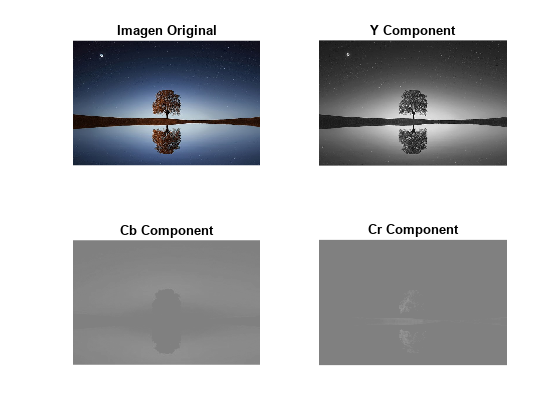

arbol_YCbCr = RGBtoYCbCr(arbol);

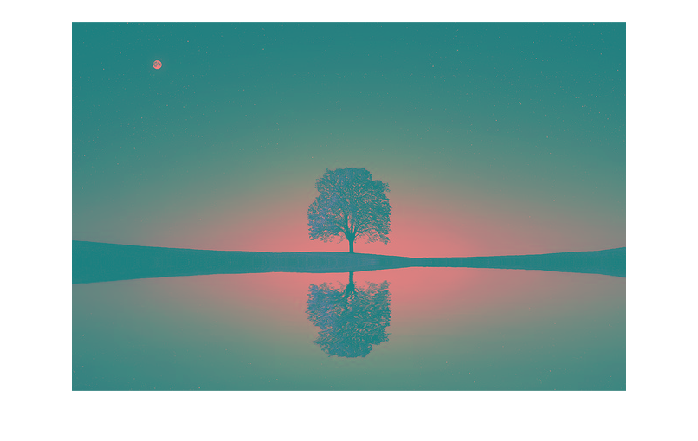

figure;
imshow(arbol_YCbCr);

## Ejercicio 2

#### 2.1

caballos = "caballos_640x427.jpg";
arbol = "arbol_640x426.jpg";
niebla = "niebla_640x456.jpg";

% Carga y conversión de las imagenes a escala de grises
caballos_gris = rgb2gray(imread(caballos));
arbol_gris = rgb2gray(imread(arbol));
niebla_gris = rgb2gray(imread(niebla));


% Calculo de la entropía de las imagenes
entropia_caballos = CalculaEntropia(caballos_gris);
entropia_arbol = CalculaEntropia(arbol_gris);
entropia_niebla = CalculaEntropia(niebla_gris);

% Resultado de las entropías de las imagenes
disp('Ej. 2.1')

Ej. 2.1


disp(['Entropía de la imagen de caballos: ' num2str(entropia_caballos) ' bits/pixel']);

Entropía de la imagen de caballos: 6.4665 bits/pixel


disp(['Entropía de la imagen de arbol: ' num2str(entropia_arbol) ' bits/pixel']);

Entropía de la imagen de arbol: 7.3369 bits/pixel


disp(['Entropía de la imagen de niebla: ' num2str(entropia_niebla) ' bits/pixel']);

Entropía de la imagen de niebla: 7.4851 bits/pixel


#### 2.2

% Concatenación las imágenes en un solo vector
vector_conjunto = [caballos_gris(:); arbol_gris(:); niebla_gris(:)];

% Calcular la entropía conjunta
entropia_conjunta = CalculaEntropia(vector_conjunto);

% Mostrar la entropía conjunta
disp('Ej. 2.2')

Ej. 2.2


disp(['Entropía conjunta de las imágenes: ' num2str(entropia_conjunta) ' bits/pixel']);

Entropía conjunta de las imágenes: 7.5777 bits/pixel


## Ejercicio 3

#### 3.1

% Imagen en escala de grises
icono = "icono_8x8.jpg";
icono_gris = rgb2gray(imread(icono));

% Conversión de la imagen a blanco y negro
imagen_bw = imbinarize(icono_gris);

% Mostrar las imágenes
disp('Ej. 3.1')

Ej. 3.1


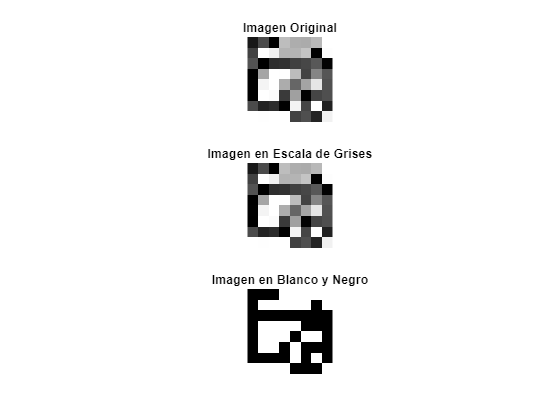

figure;
subplot(3, 1, 1);
imshow(icono);
title('Imagen Original')

subplot(3, 1, 2);
imshow(icono_gris);
title('Imagen en Escala de Grises');

subplot(3, 1, 3);
imshow(imagen_bw);
title('Imagen en Blanco y Negro');

#### 3.2

% Histograma de la imagen blano y negro
histograma = imhist(imagen_bw);

% Calcular la probabilidad de ocurrencia de cada símbolo
total_pixeles = numel(imagen_bw);
probabilidades = histograma / total_pixeles;

% Mostrar las probabilidades
disp('Ej. 3.2')

Ej. 3.2


disp('Probabilidad de ocurrencia del color negro (símbolo 0):');

Probabilidad de ocurrencia del color negro (símbolo 0):


disp(probabilidades(1));

    0.5312



disp('Probabilidad de ocurrencia del color blanco (símbolo 1):');

Probabilidad de ocurrencia del color blanco (símbolo 1):


disp(probabilidades(2));

    0.4688



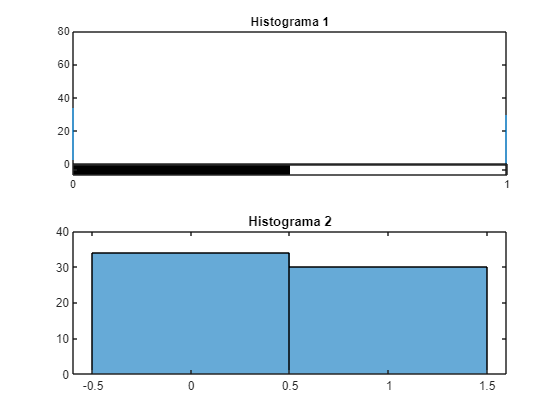


% Plot 
figure;
subplot(2, 1, 1); 
imhist(imagen_bw); 
title('Histograma 1');

subplot(2, 1, 2);
histogram(imagen_bw);
title('Histograma 2')

#### 3.3

% Calculo de los códigos Huffman
simbolos = [0 1];
prob = transpose(probabilidades);
codHuff = CalcularCodHuffman(prob);

% Mostrar códigos
disp('Ej. 3.3')

Ej. 3.3


disp('Código Huffman del color negro (símbolo 0):');

Código Huffman del color negro (símbolo 0):


disp(codHuff(1));

1


disp('Código Huffman  del color blanco (símbolo 1):');

Código Huffman  del color blanco (símbolo 1):


disp(codHuff(2));

0


#### 3.4

% Conversión a decimal el código binario y obtención el rendimiento del codificador
entropia_img = CalculaEntropia(imagen_bw);
decodedDecimal = binary2decimal(codHuff);
efficiency = calcular_eficiencia(entropia_img, prob, codHuff);

% Resultados
disp('Ej. 3.4')

Ej. 3.4


disp(['Números decimales: ' num2str(decodedDecimal)]);

Números decimales: 1  0


disp(['Eficiencia: ' num2str(efficiency)]); 

Eficiencia: 0.99718
